## Gráfica del campo de desplazamientos

% Datos del problema 
xOrg = 0; % Origen x-dir
yOrg = 0; % Origen y-dir
L = 1; % Longitud en las direcciones x e y

% Genereación del mallado 2D
x = xOrg:0.05:L;
y = yOrg:0.05:L;
[X, Y] = meshgrid(x, y);

% Cálculo del campo de desplazamientos
ux = sin(2*pi*X/L).*cos(2*pi*Y/L); % Componente u del campo de desplazamientos
vy = -cos(2*pi*X/L).*sin(2*pi*Y/L); % Componente v del campo de desplazamientos

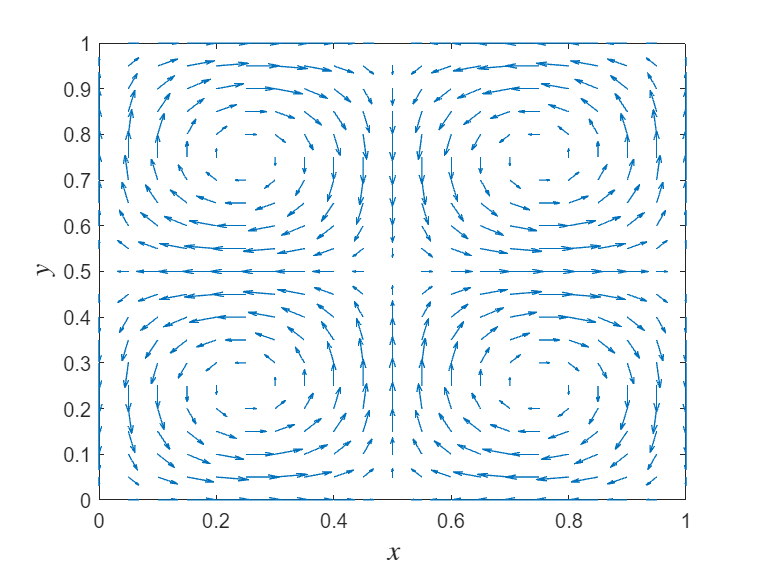

% Gráfica del campo de desplazamientos
quiver(X, Y, ux, vy)
xlabel('$x$', 'Interpreter','latex', 'FontSize', 14)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 14)
xlim([min(X(:)) max(X(:))]);
ylim([min(Y(:)) max(Y(:))]);

## **Gráfica del vector de rotación**

% Cálculo del campo escalar
rotVect = (4*pi/L)*sin(2*pi*X/L).*sin(2*pi*Y/L);

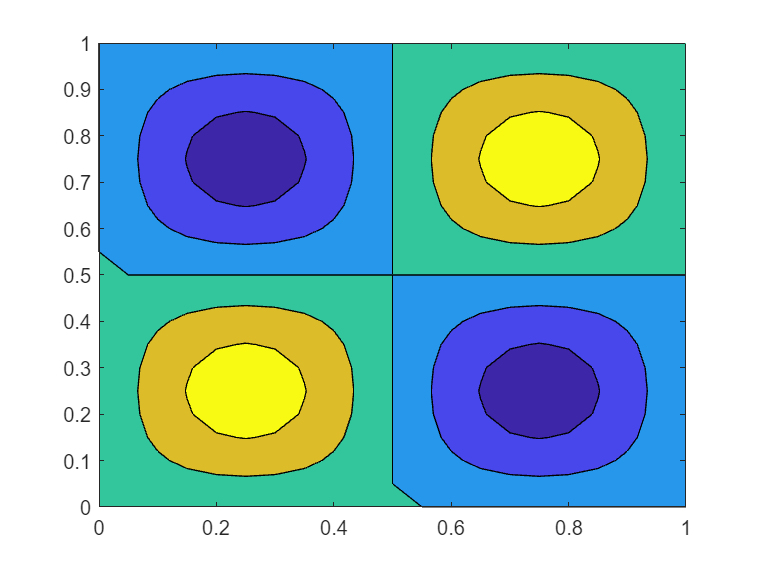

% Gráfica del vector de rotación como un campo escalar
contourf(X, Y, rotVect)
colormap parula